## APPROSSIMAZIONE DI AUTOVALORI E AUTOVETTORI

Sia $A\in\mathbb{C}^{n\times n}$, $A\underline{x}=\lambda\underline{x}$, con $\lambda$autovalore e $\underline{x}$ autovettore associato a $\lambda$

Richiamiamo la definizione di quoziente di Rayleigh:  $\frac{\underline{x}^HA\underline{x}}{\underline{x}^H\underline{x}}=\lambda$ , dove $^H$ indica il trasposto coniugato

#### Localizzazione degli autovalori

Teorema (di Gershgorin, 1):

               Sia $A\in\mathbb{C}^{n\times n}$, allora:

                                    $\sigma(A)\subseteq S_R=\bigcup^n_{i=1}R_i$,          $R_i=\left\{z\in\mathbb{C}: \ \mid z-A_{ii}|\leq\sum_{j=1, \ i\neq j}^n\mid A_{ij}\mid  \right\}$

                                    $\sigma(A)\subseteq S_C=\bigcup^n_{j=1}C_j$,        $C_j=\left\{z\in\mathbb{C}: \ \mid z-A_{jj}|\leq\sum_{i=1, \ i\neq j}^n\mid A_{ij}\mid  \right\}$

                     e inoltre, $\sigma(A)\subseteq S_R\cap S_C$

esempio grafico:

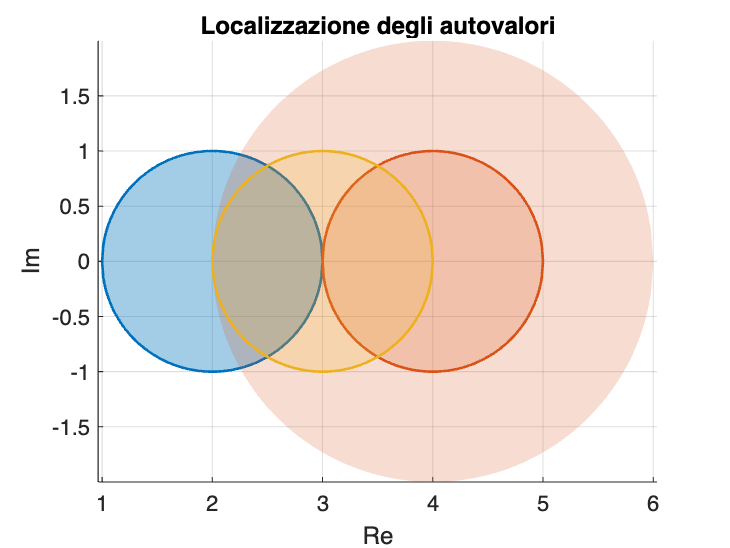

fc = @(x, r) sqrt(r^2 - x.^2);  % Semicerchio

A = [2, 1 , 0; 1, 4, 1; 0, 0, 3];
n = size(A, 1);

colors = lines(n);  % N colori distinti

hold on
grid on
axis equal

for i = 1:n
    xi = A(i,i);  % Centro

    % Raggio dalla riga
    r_row = sum(A(i, :)) - xi;
    xx = linspace(xi - r_row, xi + r_row, 200);
    yy = fc(xx - xi, r_row);
    
    % Semicerchio superiore (riga)
    fill([xx, fliplr(xx)], [yy, zeros(size(yy))], colors(i,:), ...
        'FaceAlpha', 0.2, 'EdgeColor', 'none');
    
    % Semicerchio inferiore (riga)
    fill([xx, fliplr(xx)], [-yy, zeros(size(yy))], colors(i,:), ...
        'FaceAlpha', 0.2, 'EdgeColor', 'none');

    % Raggio dalla colonna
    r_col = sum(A(:, i)) - xi;
    xx = linspace(xi - r_col, xi + r_col, 200);
    yy = fc(xx - xi, r_col);
    
    % Semicerchio superiore (colonna)
    fill([xx, fliplr(xx)], [yy, zeros(size(yy))], colors(i,:), ...
        'FaceAlpha', 0.2, 'EdgeColor', 'none');
    
    % Semicerchio inferiore (colonna)
    fill([xx, fliplr(xx)], [-yy, zeros(size(yy))], colors(i,:), ...
        'FaceAlpha', 0.2, 'EdgeColor', 'none');

    % Bordo curvo superiore e inferiore (opzionale)
    plot(xx,  yy, 'Color', colors(i,:), 'LineWidth', 1.2)
    plot(xx, -yy, 'Color', colors(i,:), 'LineWidth', 1.2)
end

title('Localizzazione degli autovalori')
xlabel('Re')
ylabel('Im')

Teorema (di Gershgorin, 2):

               Sia $A\in\mathbb{C}^{n\times n}$, $S_1=\bigcup_{i=1}^mR_i, \  S_2=\bigcup_{i=m+1}^n R_i$   

               Se $S_1\cap S_2=\emptyset
$, allora:

                          - $S_1$ contiene $m$ autovalori (contati con la loro molteplicità algebrica)

                          - $S_2$ contiene $n-m$ autovalori (contati con la loro molteplicità algebrica)

Teorema (Bauer-Ficke, perturbazione dello spettro):

              Sia $A\in\mathbb{C}^{n\times n}$ diagonalizzabile e $E\in\mathbb{C}^{n\times n}$. Sia $\mu\in\sigma(A+E)$,

                    allora: 

                                $\min_{\lambda\in\sigma(A)}\mid\lambda-\mu\mid\leq k_2(X)\|E\|$, 

                                                                            dove $X^{-1}AX=D$ con $D=diag(\lambda_1, \dots,\lambda_n)$

            Questo teorema ci dà una stima della distanza tra gli autovalori della matrice $A$ e quelli della             matrice perturbata 

### Metodo delle potenze diretto

Obbiettivo: approssimare l'**autovalore di modulo massimo** e il corrispettivo autovettore di norma 1 di una matrice $A\in\mathbb{C}^{n\times n}$

Assunzioni iniziali:

                               -  A diagonalizzabile

                               - $\lambda_{max}$ unico

Algoritmo:

function [lambda,q,iter]=eigpower(A,tol,nmax,x0)

q = x0/norm(x0);

lambda = conj(q') * A * q;

err = tol * abs(lambda) + 1;

iter = 0;

while iter < nmax &&  err > tol

    z = A * q;
    q = z/norm(z);

    lambda_prec = lambda;

    lambda = conj(q') * A * q;

    err = abs(lambda - lambda_prec)/abs(lambda);

    iter = iter +1;

end

end

Osservazioni: 

                        - se $\lambda_{max}$ non è unico, il vettore restituito dall'algoritmo è combinazione lineare di due autovettori

                        - se $\lambda_{max}=-\lambda_2$, applico il metodo delle potenze alla matrice $A^2$ e ricado nel caso precedente

                        - se $\lambda_{max}=\overline{\lambda}_2$, il metodo non converge

#### Criteri di arresto

1) $\mid Aq^{(k)}-\nu^{(k)}q^{(k)}\mid\leq\varepsilon$

2) $\mid\nu^{(k+1)}-\nu^{(k)}\mid\leq\varepsilon$

### Metodo delle potenze inverso

Obbiettivo: approssimare l'**autovalore di modulo minimo** e il corrispettivo autovettore di norma 1 di una matrice$A\in\mathbb{C}^{n\times n}$

Ricordo che $\lambda(A^{-1})=\frac{1}{\lambda(A)}$

Algoritmo:

function [mu,x,iter]=invpower(A,tol,nmax,x0)


[L, U, P] = lu(A);

q = x0/norm(x0);

mu = conj(q') * A * q;

err = tol * abs(mu) + 1;

iter = 0;

while iter < nmax &&  err > tol && abs(mu) ~= 0

    y = fwsub(L, P*q);
    z = bksub(U, y);
    q = z/norm(z);

    mu_prec = mu;

    mu = conj(q') * A * q;

    err = abs(mu - mu_prec)/abs(mu);

    iter = iter +1;

end
x = q;

end

### Metodo delle potenze con shift

Obbiettivo: approssimare l'**autovalore di modulo più vicino a **$\mu$ ovvero $\overline{\lambda}:=\arg\min_{\lambda\in\sigma(A)}\mid \lambda-\mu\mid$ 

                  e il corrispettivo autovettore di norma 1 di una matrice$A\in\mathbb{C}^{n\times n}$

function [lambda,x,iter]=invpowershift(A, mu, tol , nmax , x0)

n = size(A, 1);
M = A - mu * eye(n);

[L, U, P] = lu(M);

q = x0/norm(x0);

lambda = conj(q') * A * q;

err = tol * abs(lambda) + 1;

iter = 0;

while iter < nmax &&  err > tol && abs(lambda) ~= 0

    y = fwsub(L, P*q);
    z = bksub(U, y);
    q = z/norm(z);

    lambda_prec = lambda;

    lambda = conj(q') * A * q;

    err = abs(lambda - lambda_prec)/abs(lambda);

    iter = iter +1;

end
x = q;

end